# Feedback Amplifier Design

This script shows the designing process for a non-inverting feedback amplifier using the Control Systems Toolbox.

The design is based on the operational amplifier (op-amp), which is a standard buidling block in electrical circuits

- An operational amplifier is a modern implementation of Harold Black's feedback amplifier and is a universal component that is widely used for instrumentation, control, and communication

- Very versatile as any linear system can be implemented by combining operational amplifiers with resistors and capacitors, most notely, analog proportional-integral-derivative controllers

## Op-Amp Description

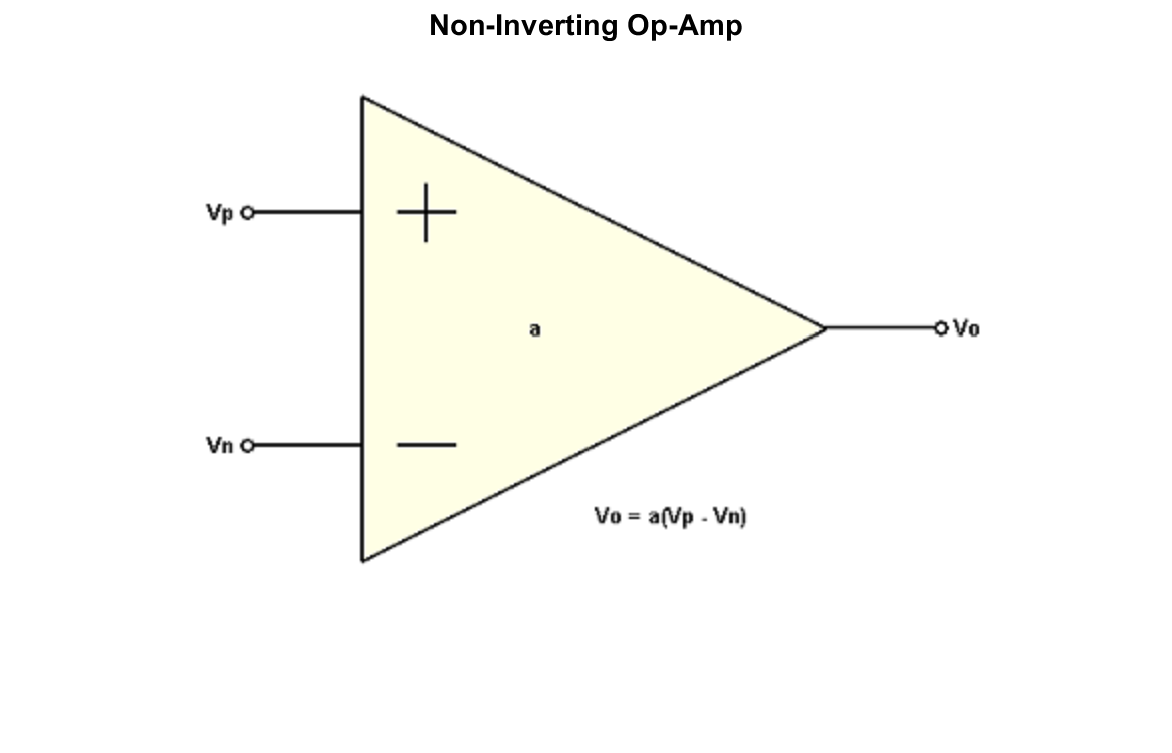

clc; close all; clear;
f = imread('OpAmp.png'); imshow(f), title('Non-Inverting Op-Amp')

The Open-Loop Transfer Function can be described as:


$$A(s) = \frac{A_0}{(1 + s/\omega_1)(1 + s/\omega_2)}$$



$$\textrm{The}\;\textrm{value}\;\textrm{of}\;A_0 \;\textrm{is}\;\textrm{ideally}\;\infty \;\textrm{but}\;\textrm{typically}\;\textrm{within}\;\textrm{the}\;\textrm{range}\;\textrm{of}\;{10}^6 -{10}^8 \;\textrm{in}\;\textrm{most}\;\textrm{practical}\;\textrm{Op}\;\textrm{Amp}\;\textrm{ICs}$$


#### Assume Values and Create Transfer Function

A0 = 1e5; w1 = 1e4; w2 = 1e6;
s = tf('s');
A_open = A0/(1 + s/w1)/(1 + s/w2)

A_open =
 
           1e15
  ----------------------
  s^2 + 1.01e06 s + 1e10
 
Continuous-time transfer function.



#### Plot Pole-Zero Map 

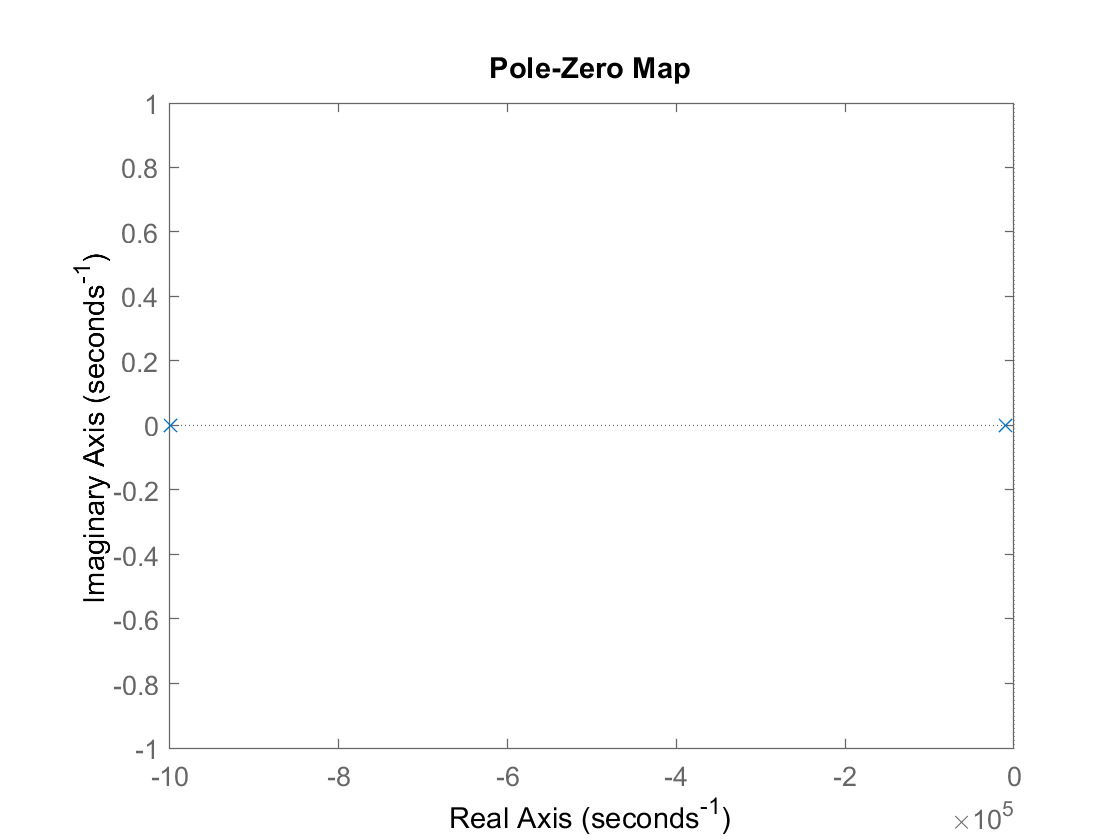

figure, pzmap(A_open)

Transfer Function has two real poles at 


$$\omega_1 = 10,000 \text{ and } \omega_2 = 1,000,000 $$


#### Display Bode Plot for Transfer Function

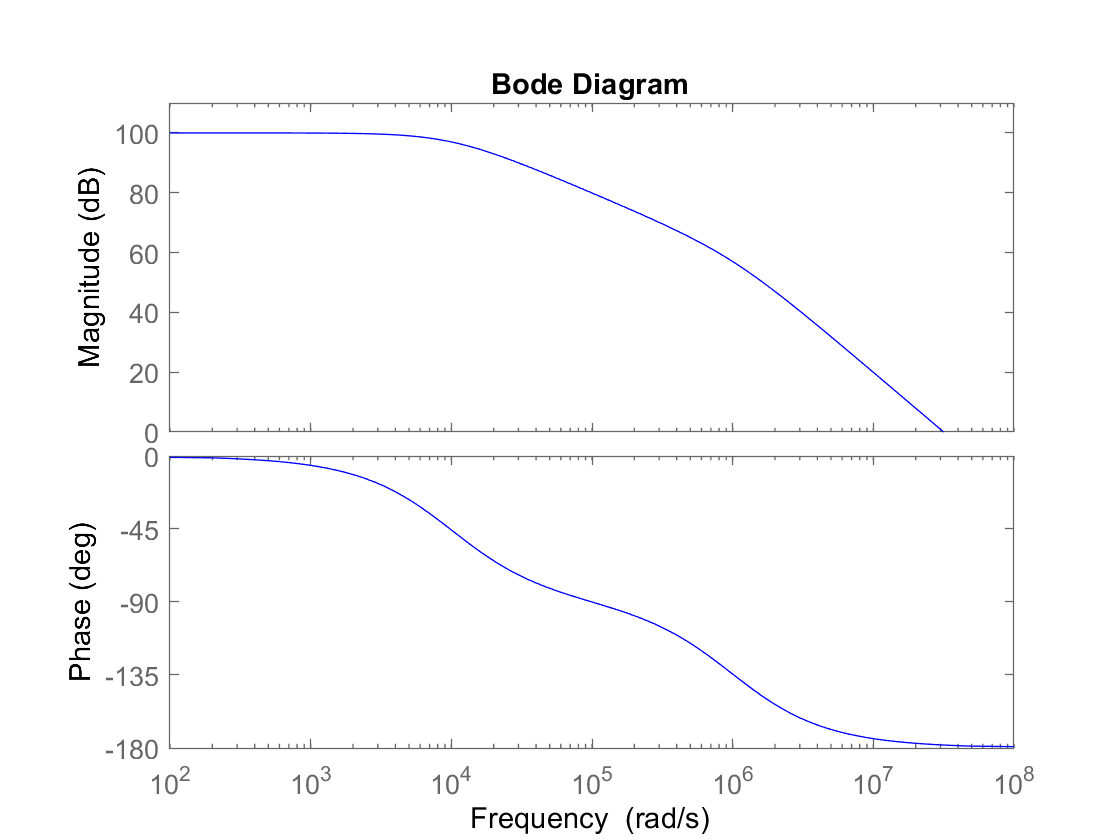

h = bodeplot(A_open,'b');
setoptions(h,'FreqUnits','rad/s','MagUnits','dB','PhaseUnits','deg',...
    'YLimMode','Manual','YLim',{[0,110],[-180,0]});

#### View the Normalized Open-Loop Step Response of System

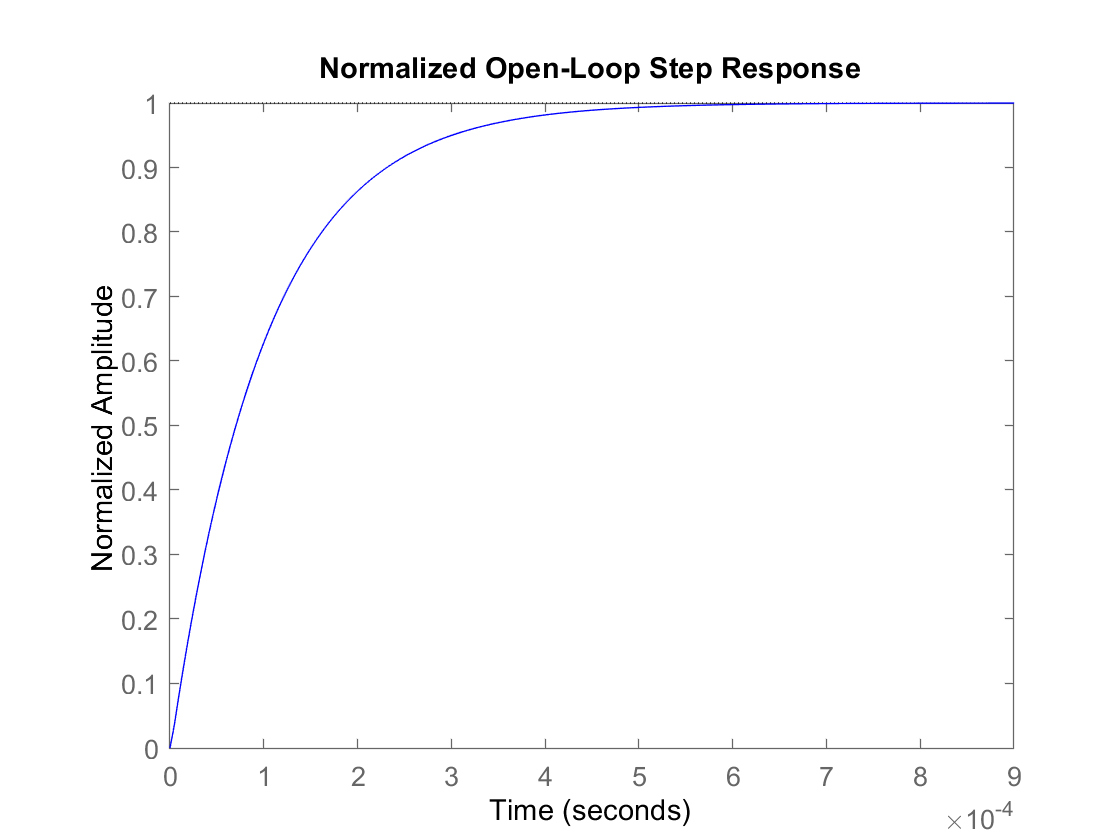

A_norm = A_open / dcgain(A_open);
stepplot(A_norm,'b')

title('Normalized Open-Loop Step Response');
ylabel('Normalized Amplitude');

## Feedback Amplifier 

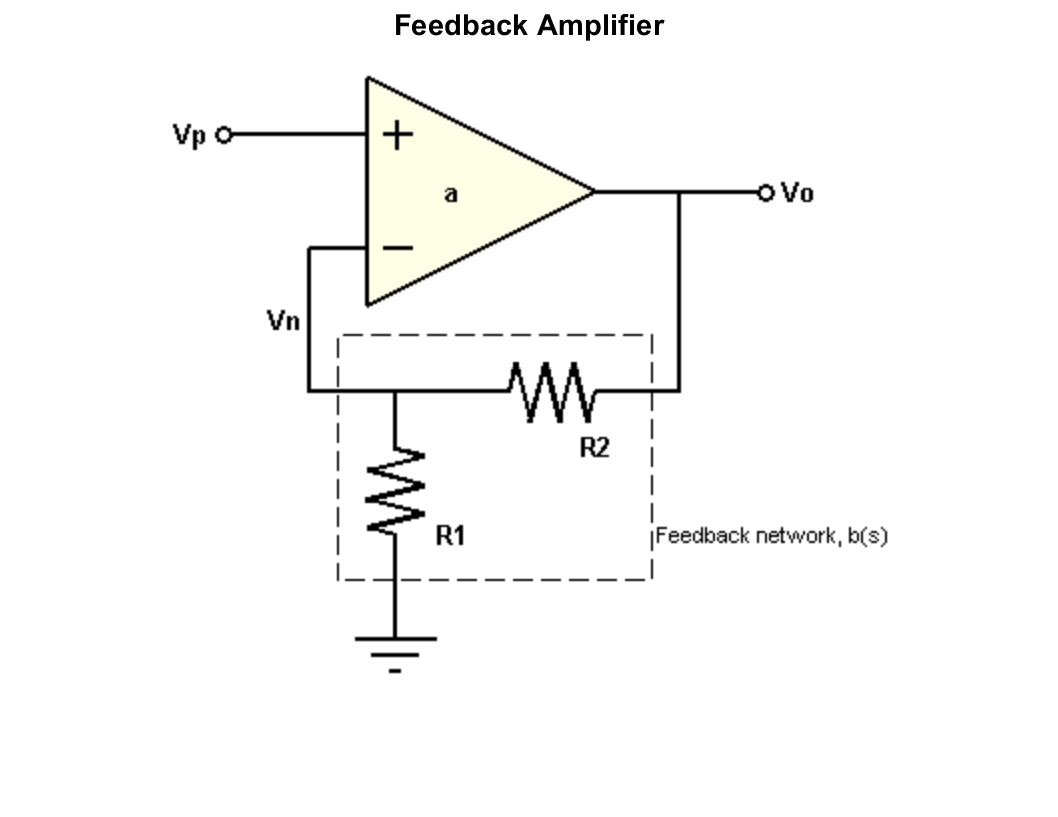

f = imread('FeedbackAmplifier.png'); imshow(f), title('Feedback Amplifier')

The Feedback network, $B(s)$ is voltage divider between input $V_n$ and output $V_o$ . Solving for this ratio gives the transfer function: 


$$B = \frac{V_o}{V_n} = \frac{R_1}{R_1 + R_2}$$


#### The Closed-Loop Diagram:

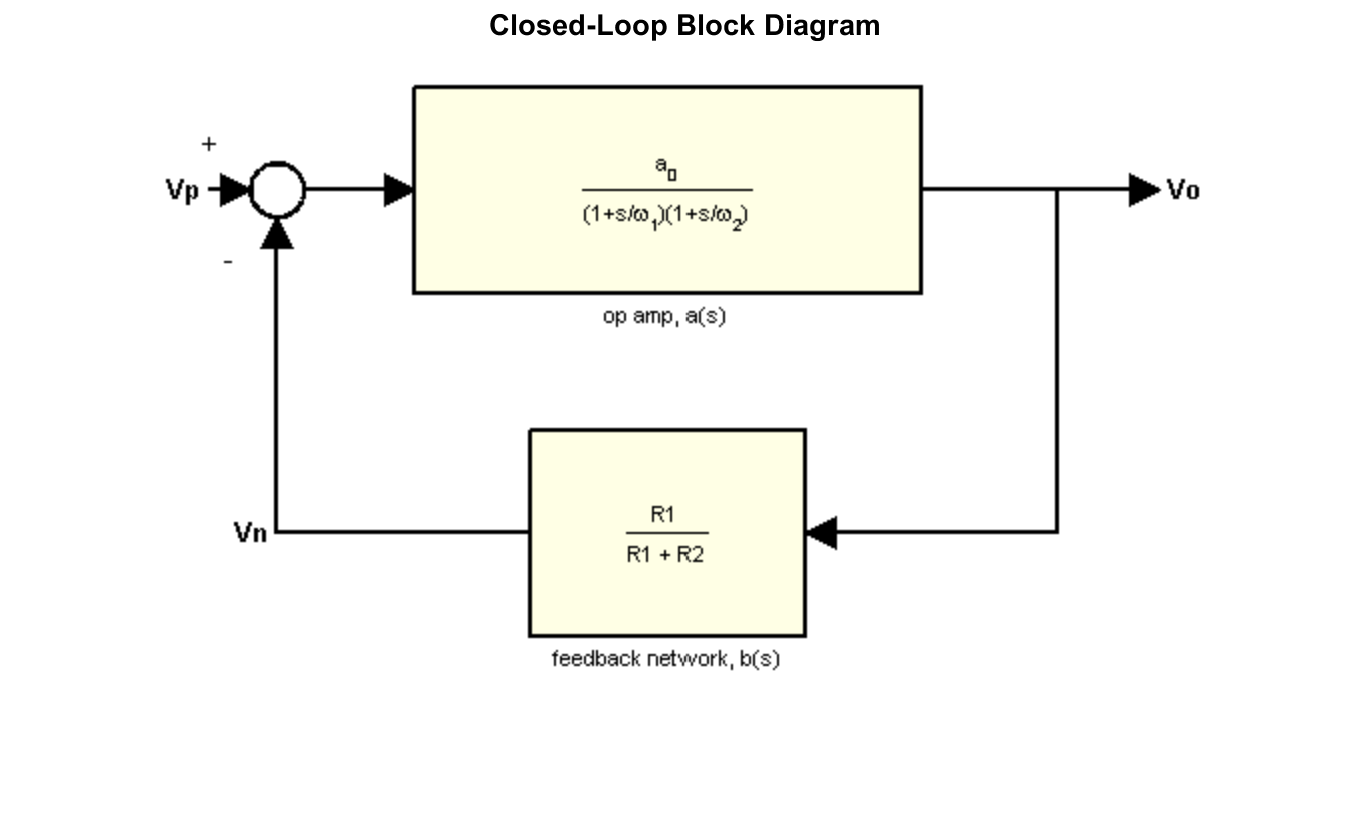

f = imread('ClosedLoopGain.png'); imshow(f), title('Closed-Loop Block Diagram')

The ratio of the closed-loop gain would then be


$$A = \frac{V_o}{V_p} = \frac{A}{1 + AB}$$


However, if the product, $AB$, is extremely large, then the gain can be approximated too


$$A = \frac{1}{B}$$


#### Design Amplifier with DC Gain of 10 with $R_1 = 10k\Omega$. Solve for $R_2:$

A0 = 10; B = 1/A0;
R1 = 1e4; R2 = R1 * (1/B - 1)

R2 = 90000

Thus, $R_2 = 90k\Omega$ would produce the desired Gain of $A = 10 V/V$

#### Construct Closed-Loop System using Feedback() Function

A_closed = feedback(A_open,B)

A_closed =
 
           1e15
  ----------------------
  s^2 + 1.01e06 s + 1e14
 
Continuous-time transfer function.



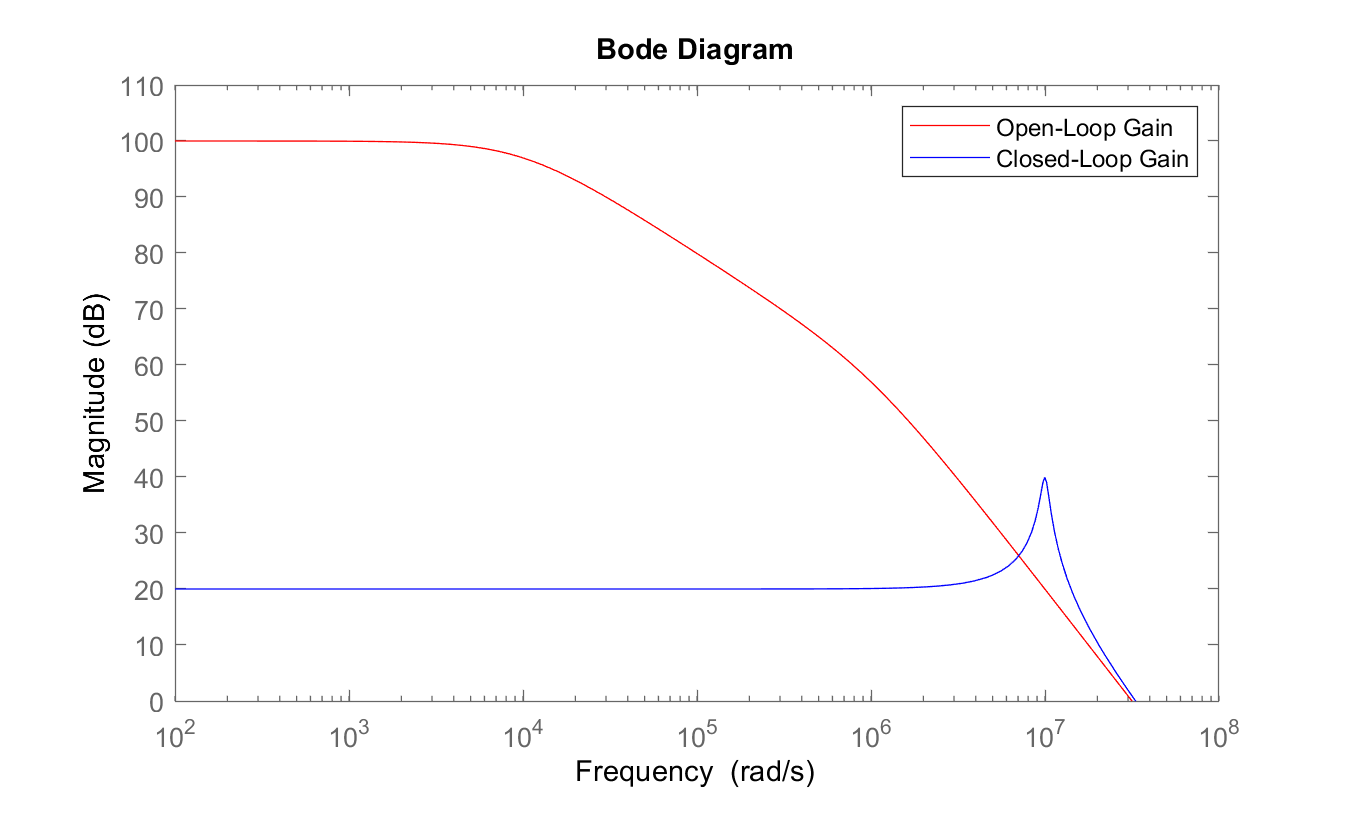

bodemag(A_open,'r',A_closed,'b');
legend('Open-Loop Gain','Closed-Loop Gain')
ylim([0,110]);

#### Observations:

- We can see that the Closed-Loop Gain is much lower for Low Frequencies, but the bandwidth has increased as a trade-off

- This Gain vs Bandwidth trade-off presents a powerful tool when designing feedback circuits

- Presents a drastic reduction in sensitivity that allows to make precise systems from uncertain components

- Feedback can be used to trade high gain and low robustness for low gain and high robustness

#### Sensitivity of the Gain to Variations

% Define Loop gain - total gain a signal experiences traveling around the
% loop
L = A_open*B;
S = 1/(1 + L);
S = feedback(1,L)

S =
 
  s^2 + 1.01e06 s + 1e10
  ----------------------
  s^2 + 1.01e06 s + 1e14
 
Continuous-time transfer function.



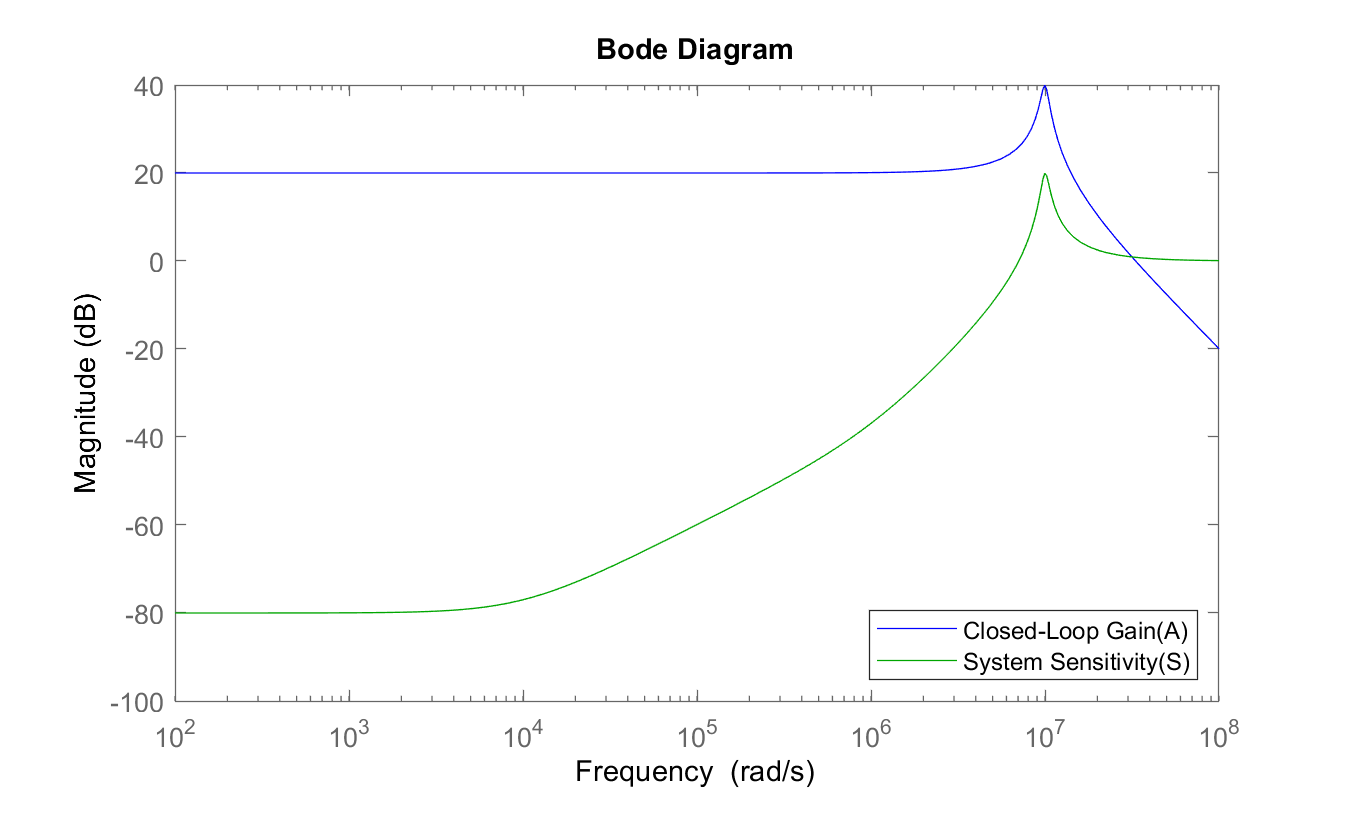

bodemag(A_closed,'b',S,'g')
legend('Closed-Loop Gain(A)', 'System Sensitivity(S)','Location','SouthEast')

The very small low-frequency sensitivity (-80 dB) indicates a design whose closed-loop gain suffers minimally from open-loop gain variation

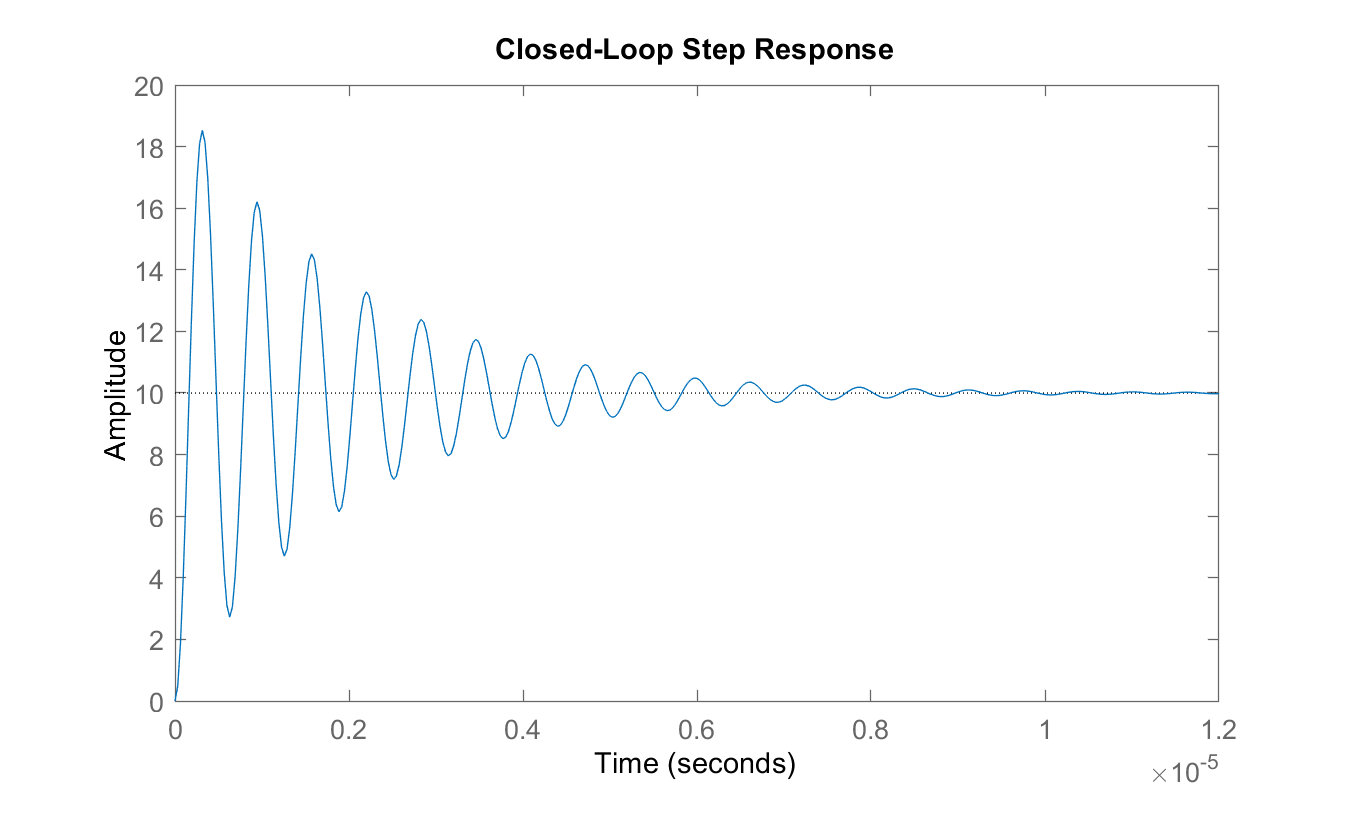

stepplot(A_closed), title('Closed-Loop Step Response')

Note that the use of feedback has greatly reduced the settling time (by about 98%). However, the step response now displays a large amount of ringing, indicating poor stability margin.

You can analyze the stability margin by plotting the loop gain, L(s)

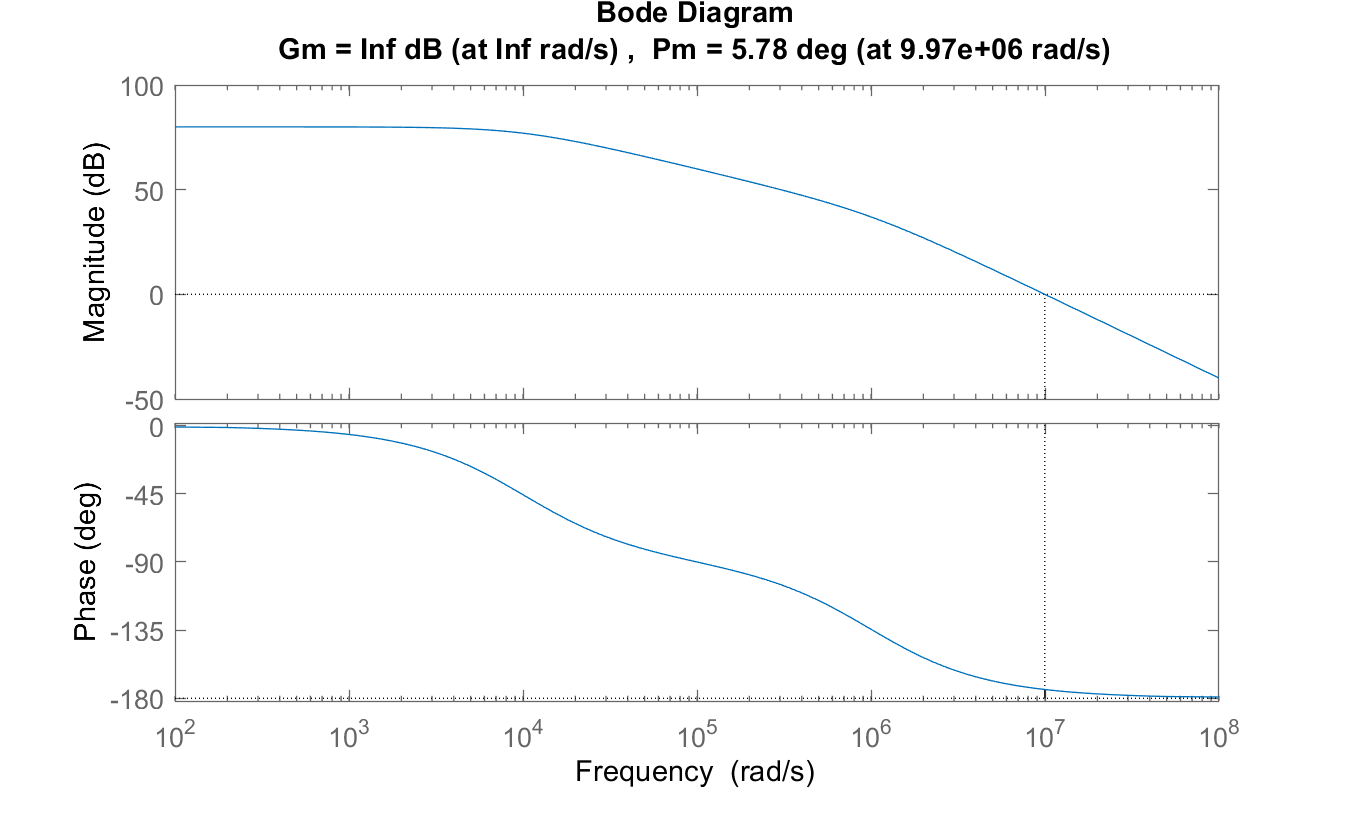

margin(L)

The resulting plot indicates a phase margin of less than 6 degrees. You will need to compensate this amplifier in order to raise the phase margin to an acceptable level (generally 45 deg or more), thus reducing excessive overshoot and ringing.

## Feedback Lead Compensation

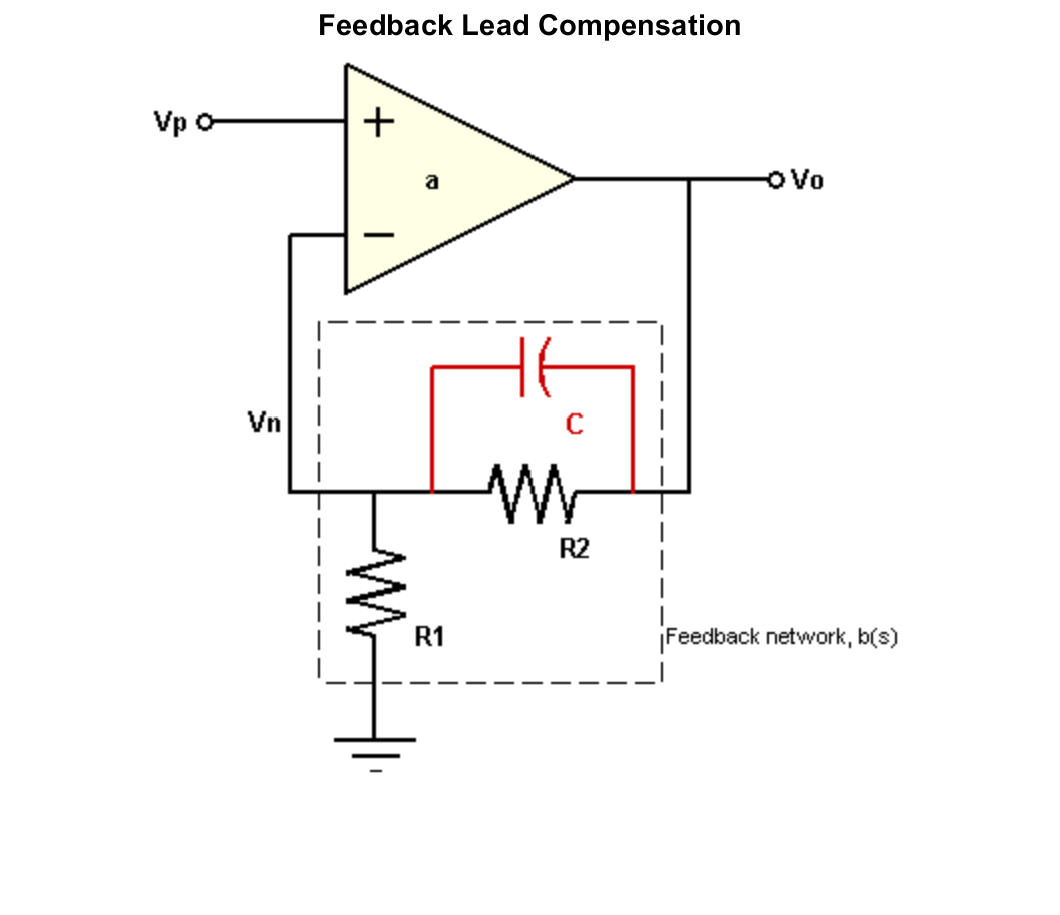

f = imread('FeedbackCompensation.png'); imshow(f), title('Feedback Lead Compensation')

A commonly used method of compensation in this type of circuit is "feedback lead compensation". This technique modifies b(s) by adding a capacitor, C, in parallel with the feedback resistor, R2

The capacitor value is chosen so as to introduce a phase lead to b(s) near the crossover frequency, thus increasing the amplifier's phase margin.

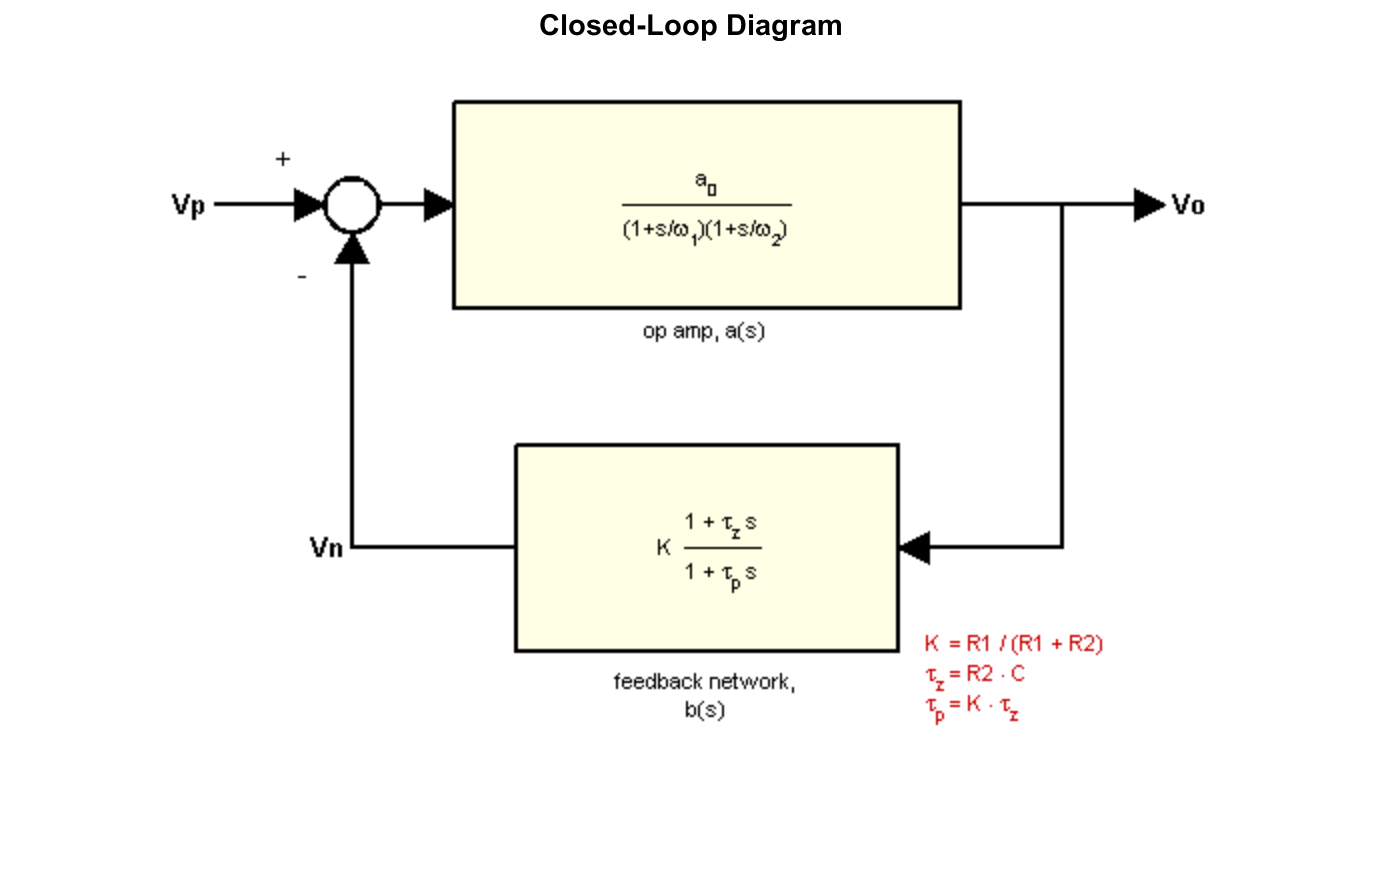

f = imread('FeedbackCompensationBlockDiagram.png'); imshow(f), title('Closed-Loop Diagram')

You can approximate a value for C by placing the zero of b(s) at the 0dB crossover frequency of L(s):

[Gm,Pm,Wcg,Wcp] = margin(L);
C = 1/(R2*Wcp)

C = 1.1139e-12


K = R1/(R1+R2);
C = [1:1/5:3]*1e-12;
for n = 1:length(C)
    B_array(:,:,n) = tf([K*R2*C(n) K],[K*R2*C(n) 1]);
end

Now you can create LTI arrays for A(s) and L(s):

A_array = feedback(A_open,B_array);
L_array = A_open*B_array;

Plot the step response for multiple values of the Capacitor:

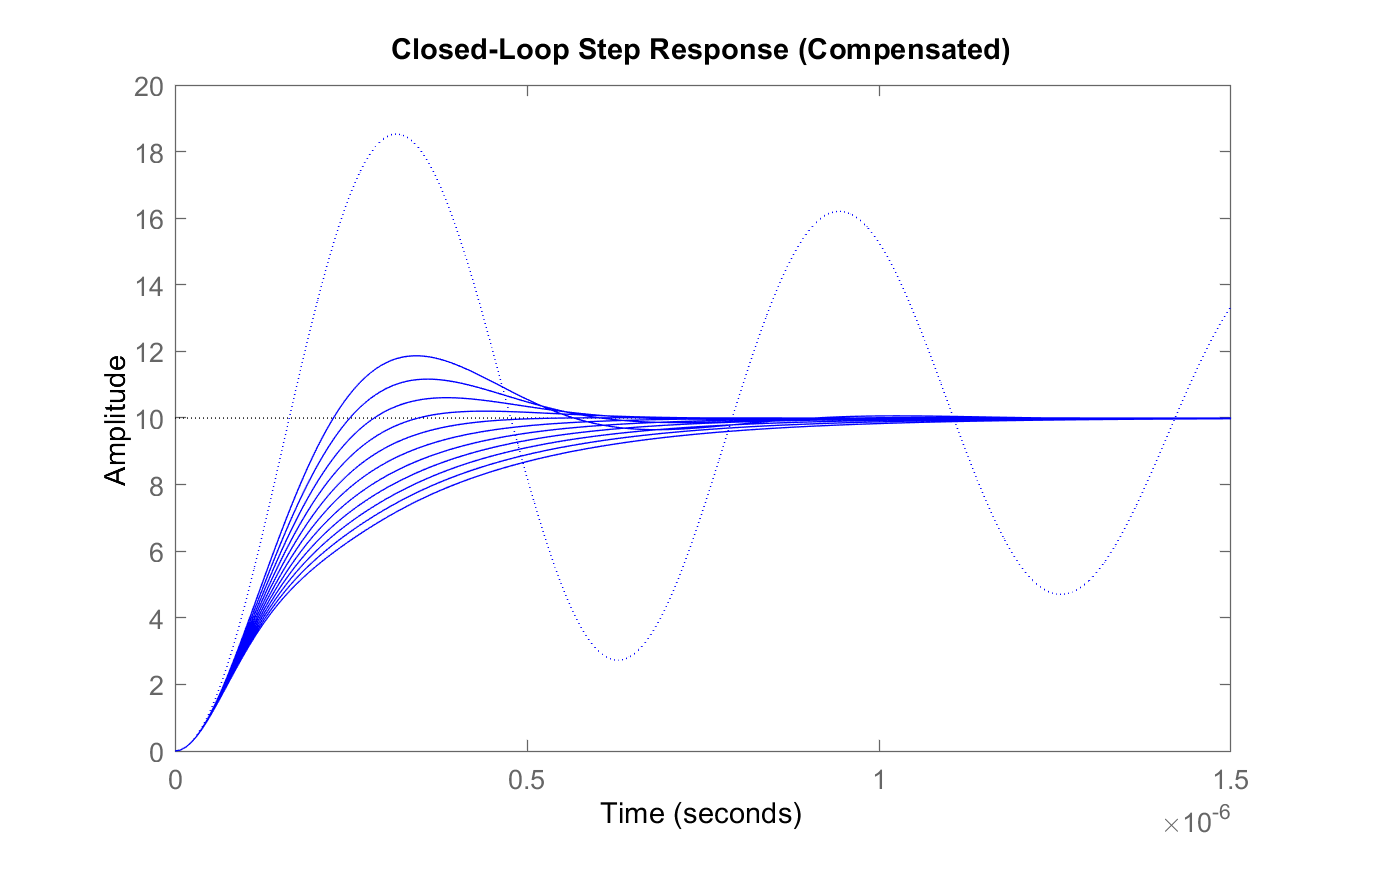

stepplot(A_closed,'b:',A_array,'b',[0:.005:1]*1.5e-6);
title('Closed-Loop Step Response (Compensated)');

## RC, RL, and RLC Circuits and their Transfer Functions

#### Simple RC Circuit

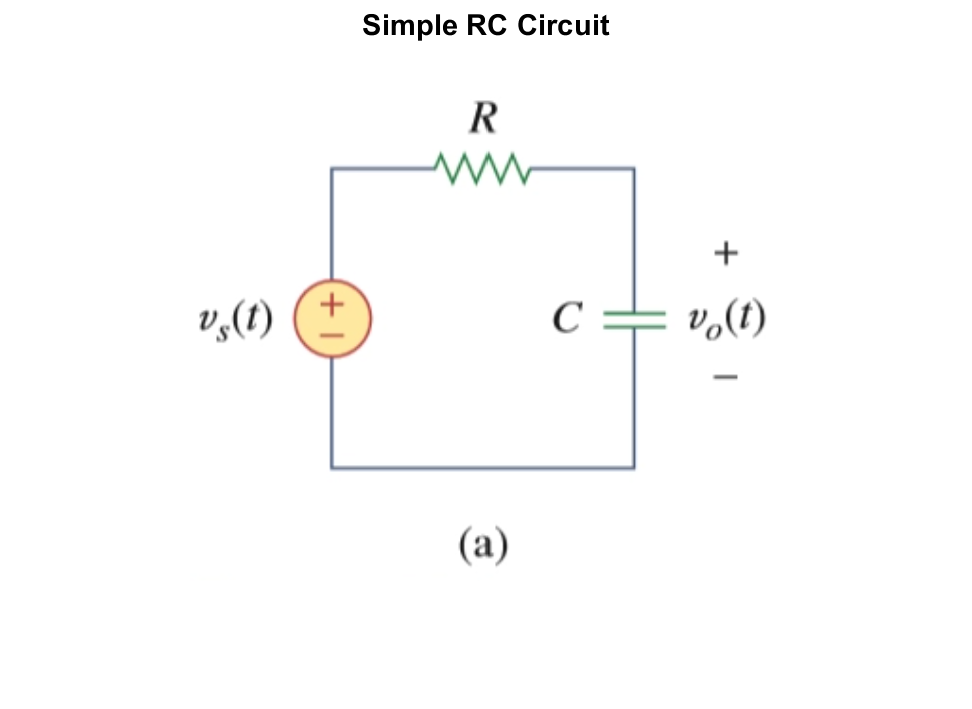

f = imread('simpleRC1.png'); figure, imshow(f), title('Simple RC Circuit')

Here, we examine the Transfer functions of different types of filters. We'll start with first-order circuits (RC or RL), then progress to second-order circuits (RLC) and examine their transfer functions

The Transfer function, $H(s)$ can be obtained from the RC circuit by:

$H(s) = \frac{V_o}{V_{in}} = \frac{1/sC}{R + sC}$ or in terms of $\omega \rightarrow H(\omega) = \frac{1/j\omega C}{R + j\omega C$

Let us create a simple example where $R = 1k\Omega$ and $C = 3\mu F$

R = 1000; C = 3e-6; s = tf('s');
H_RC = (1/(s*C))/(R + s*C), p = roots([9e-12 0.003 0])'

H_RC =
 
           1
  -------------------
  9e-12 s^2 + 0.003 s
 
Continuous-time transfer function.



p = 	1.0e+08 *

         0   -3.3333


This Transfer function has poles at $p_1 = 0 \text{ and } p_2 = -1,000,000,000$

#### Pole-Zero Map

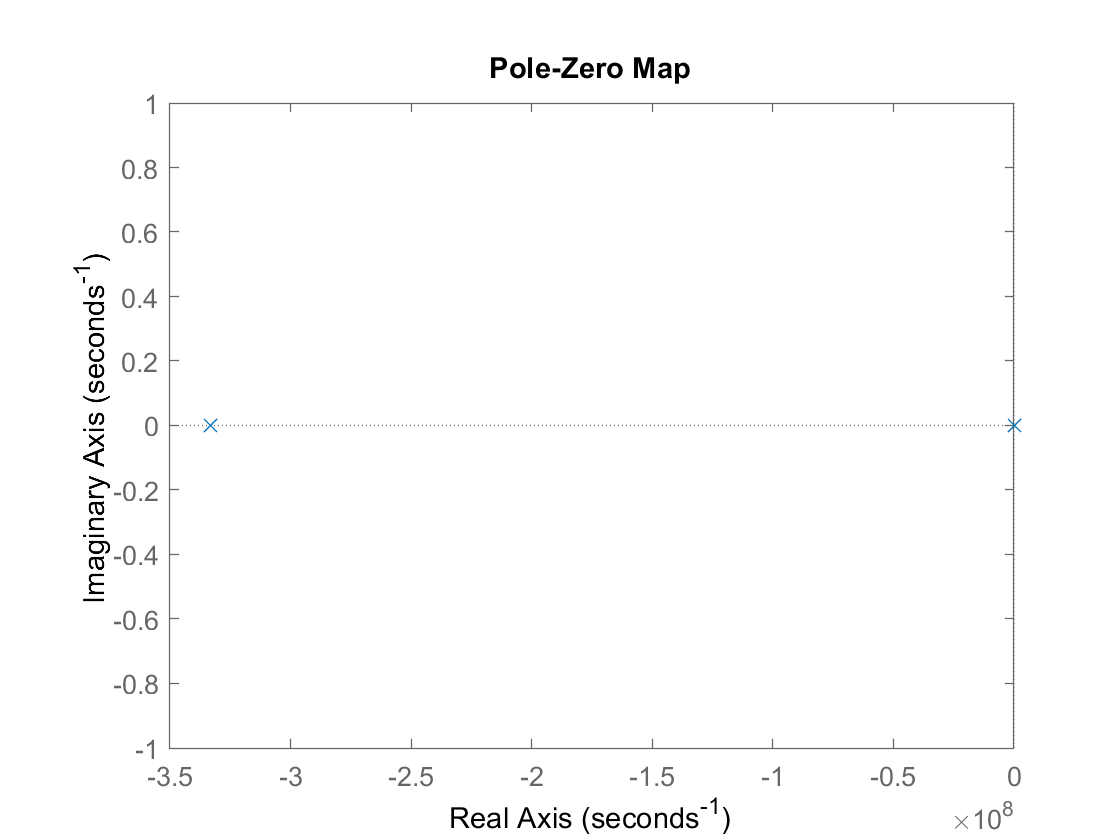

figure, pzmap(H_RC)

#### Bode Plots

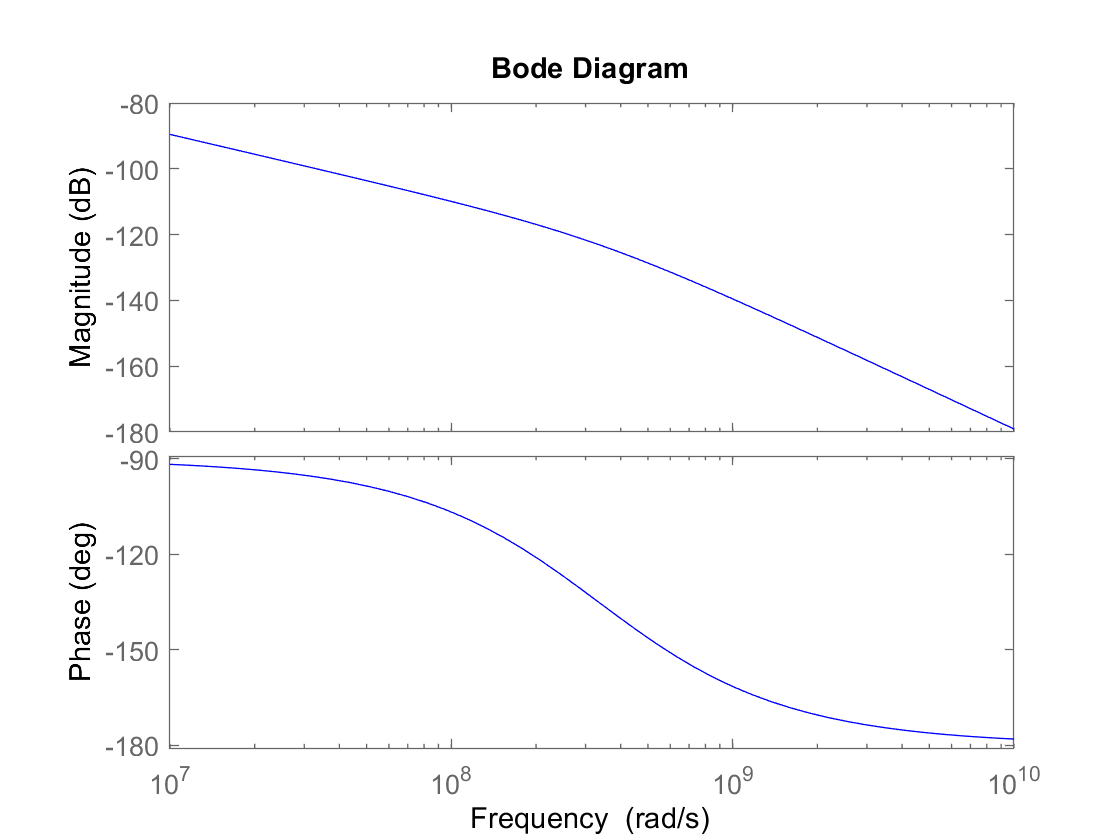

figure, RC_bode = bodeplot(H_RC,'b'); 

This Transfer Function resembles that of a Lowpass Filter 

#### Simple RL Circuit 

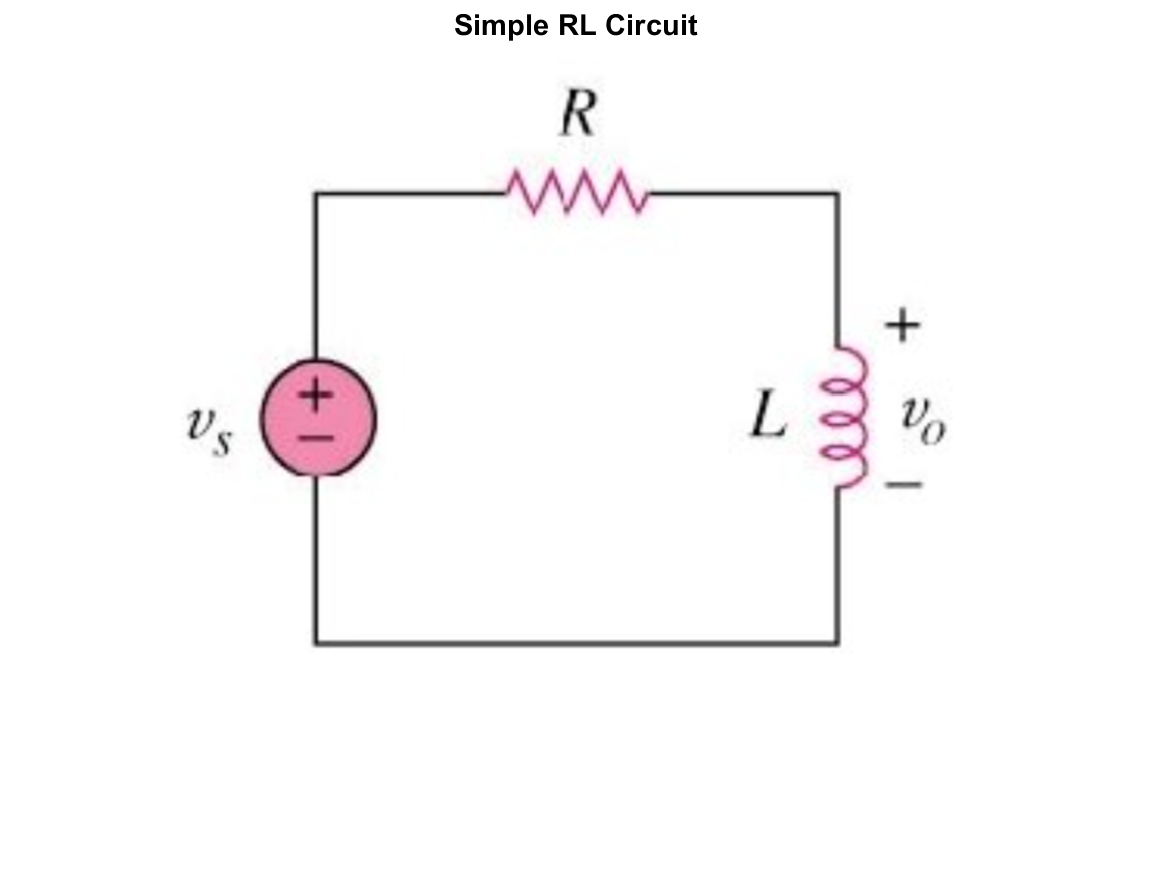

f = imread('simpleRL.png'); figure, imshow(f), title('Simple RL Circuit')

The Transfer function, $H(s)$ can be obtained from the RL circuit by:

$H(s) = \frac{V_o}{V_{in}} = \frac{sL}{R + sL}$ or in terms of $\omega \rightarrow H(\omega) = \frac{j\omega L}{R + j\omega L}$

Let us create a simple example where $R = 1k\Omega$ and $L = 3mH$

R = 1000; L = 0.003;
H_RL = (s*L)/(R + s*L), z = roots([0.003 0]), p = roots([0.003 1000])

H_RL =
 
     0.003 s
  --------------
  0.003 s + 1000
 
Continuous-time transfer function.



z = 0

p = -3.3333e+05

This Transfer function has a single pole at $p = -3.33e5$ and single zero at $z = 0$

#### Pole-Zero Map

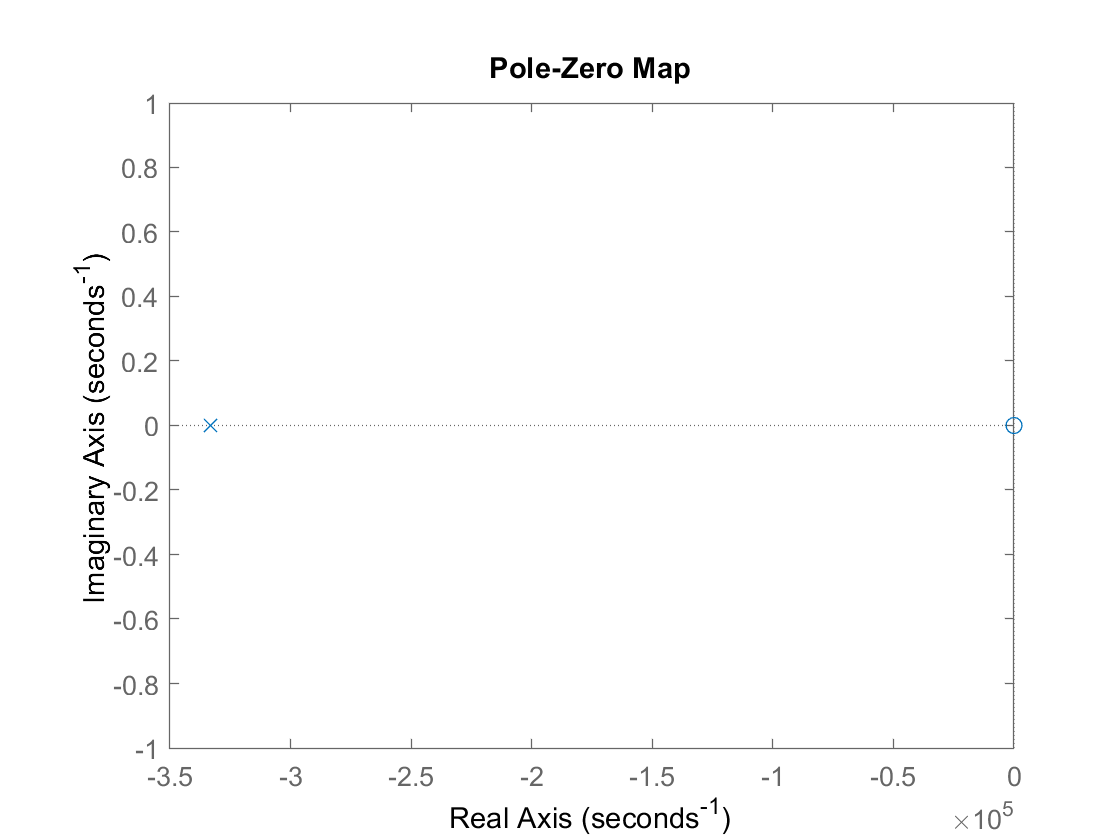

figure, pzmap(H_RL)

#### Bode Plots

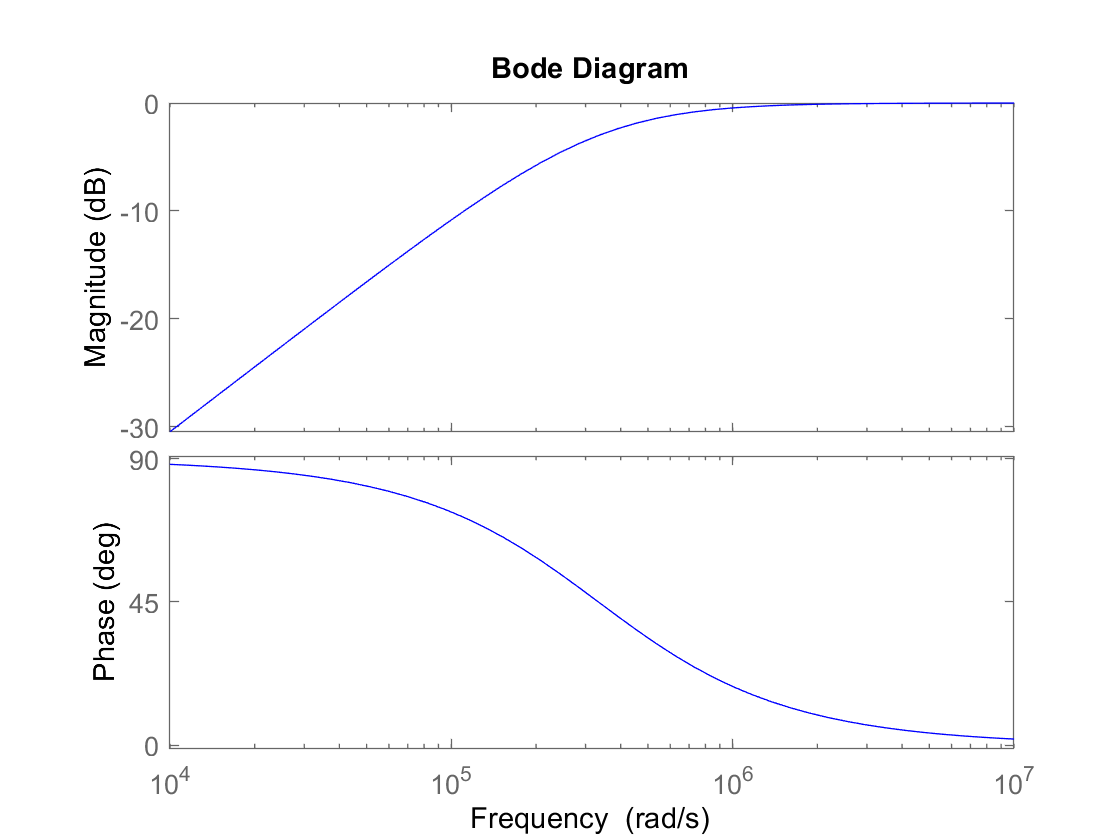

figure, RL_bode = bodeplot(H_RL,'b'); 

This Transfer function resembles that of a Highpass Filter